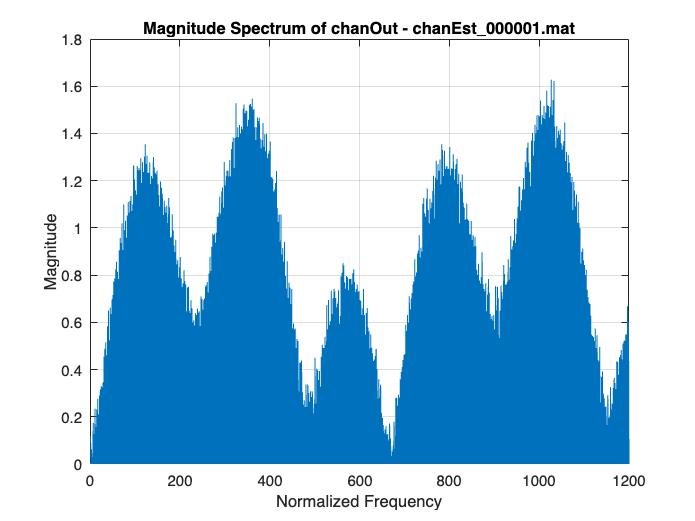

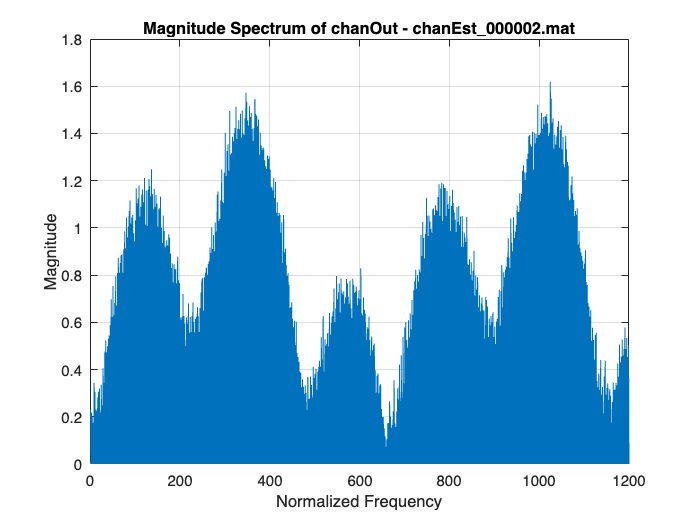

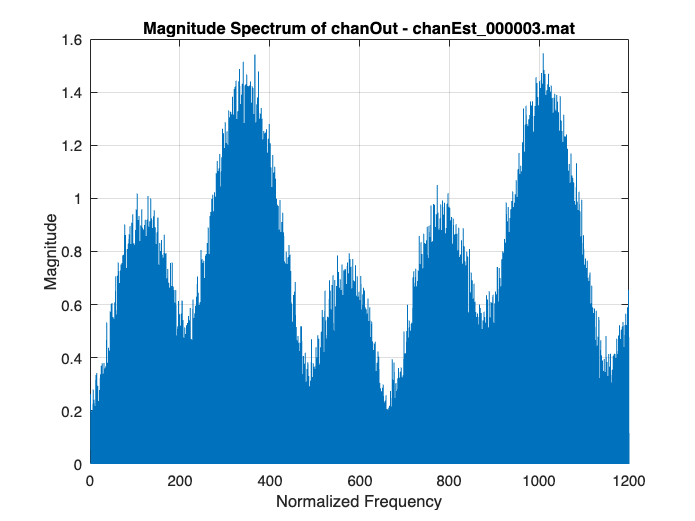

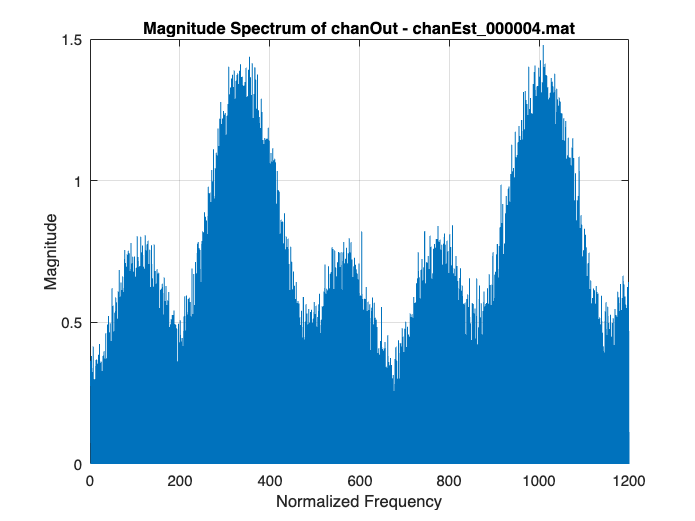

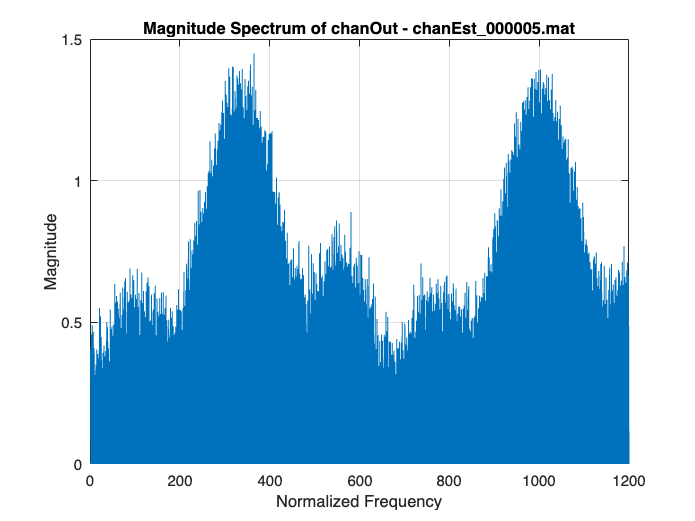

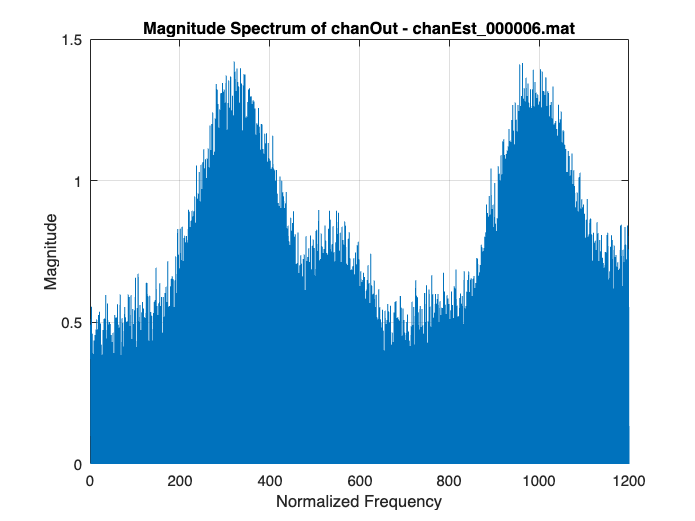

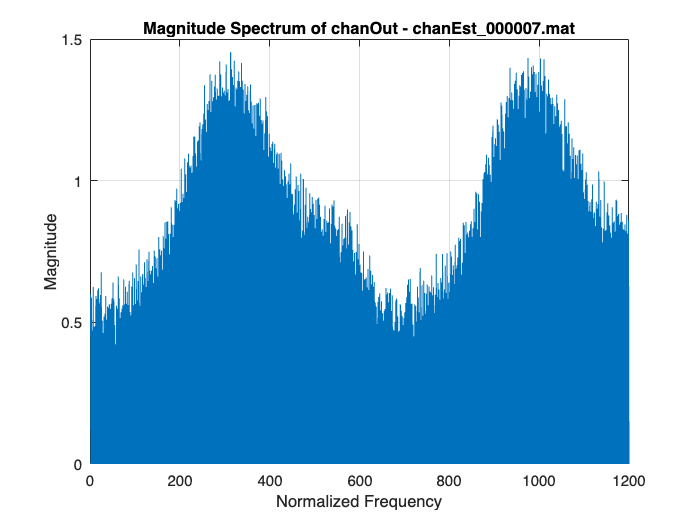

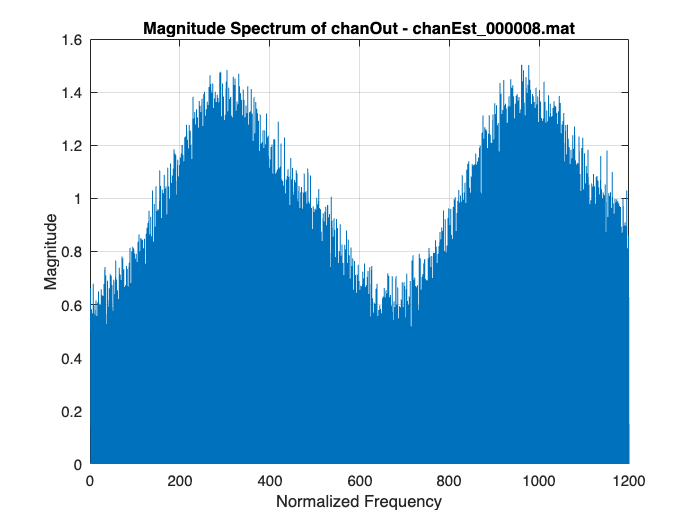

% Set folder path
folderPath = '/Users/sp33752/Documents/MATLAB/Examples/R2024b/comm/OFDMEndToEndExample/chanOutFrames4/';

% Get list of .mat files
matFiles = dir(fullfile(folderPath, '*.mat'));

% Loop through each file (adjust range as needed)
for k = 1: 27
    % Load the chanOut variable from each file
    data = load(fullfile(folderPath, matFiles(k).name));
    
    % Make sure chanOut exists in the file
    if isfield(data, 'chanEstCurrent')
        chanOut = data.chanEstCurrent;
        
      
        figure;
        plot(abs(chanOut));
        title(sprintf('Magnitude Spectrum of chanOut - %s', matFiles(k).name), 'Interpreter', 'none');
        xlabel('Normalized Frequency');
        ylabel('Magnitude');
        grid on;
    else
        warning('File %s does not contain chanOut.', matFiles(k).name);
    end
end

x=txOut

Unrecognized function or variable 'txOut'.

y=chanOut

N   = length(txOut);                   % FFT length – make them equal
Hf  = fft(chanOut, N) ./ fft(txOut,N); % frequency‑domain channel  H(f) = Y(f)/X(f)

% optional: look at it
f = (0:N-1)/N;                         % normalised frequency axis
figure
plot(f, 20*log10(abs(fftshift(Hf))));
xlabel('Normalised frequency  f / f_s'); ylabel('|H(f)| (dB)');
title('Channel frequency response  (FFT(chanOut) / FFT(txOut))'); grid on;

% List the files
files = dir('chanOutFrames3/chanEst_*.mat');
numel(files)          % → 27

% Load one file
S = load(fullfile(files(5).folder, files(5).name));
chanEst = S.chanEstCurrent;

% How many non‑zero taps?
nnz(chanEst)          % should be ~= usedSubCarr / RSSpacing

